# Dynamics Simulation 

Dynamic Simulation for the 6 DoF Space Robot

clc
load 'SR6.mat'
% sr = sr_sim;

sr.homeConfig();
q0 = sr.q;
q_dot_0 = sr.q_dot;


sr_info = SR6_info();
[xee0, xee_dot_0] = ee_speed(sr_info, q0, q_dot_0);

Parameters

fileName = '';          % Where to save animation, Do not save if left as ''
animationTEnd = 10;     % When to stop animation time

simTime = '10.0';       % Simulation end time

% Forces
fx = 0; 
fy = 0;
fz = 0;

nx = 0;
ny = 0;
nz = 0;

tau1 = 3;
tau2 = 0;
tau3 = 0;
tau4 = 0;
tau5 = 0;
tau6 = 0;

tau = [tau1; tau2; tau3; tau4; tau5; tau6];

f = -1;
dt = 1;

### Launch Simulation

% profile on
tic
set_param('open_loop_dyn', 'StopTime', simTime)
simRes = sim('open_loop_dyn');
toc

Elapsed time is 3.002168 seconds.


% profile viewer
% profile off

### Animate Results

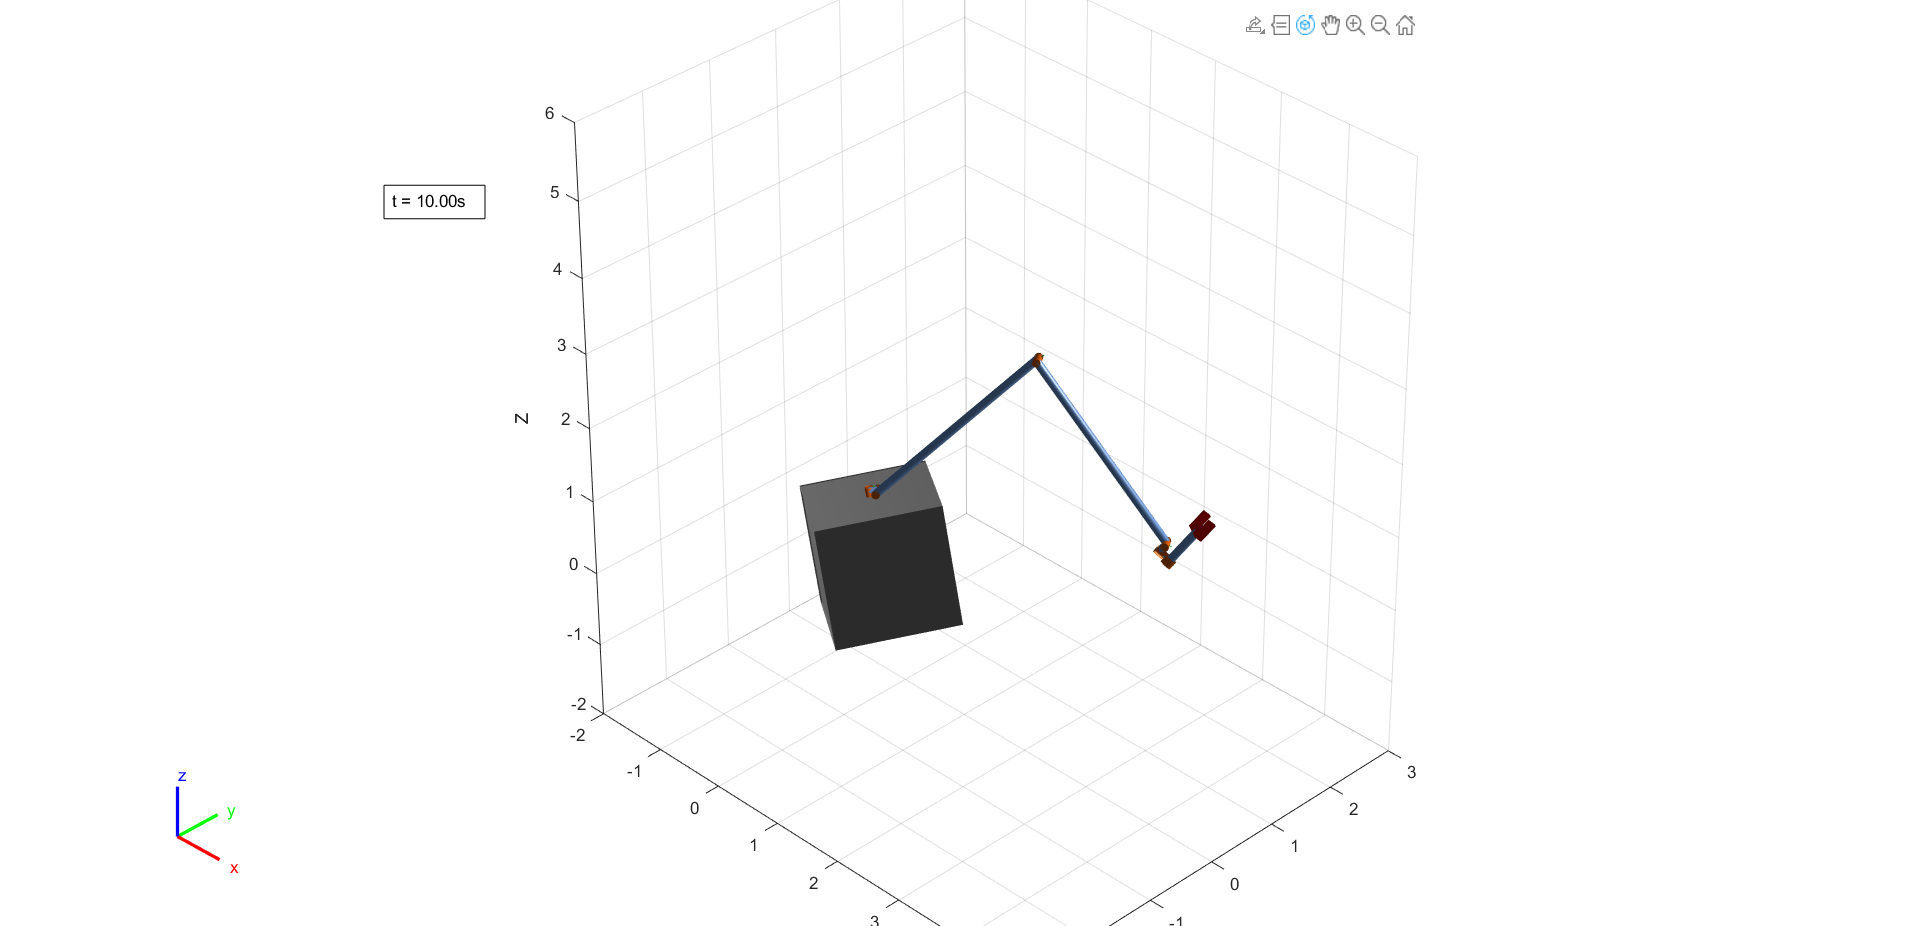

clc
close all
folder = 'Project/Videos/';

data = simRes.q.getsampleusingtime(0, animationTEnd);

if ~strcmp(fileName, '')
    savePath = strcat(folder, fileName);
else
    savePath = '';
end

tic
sr.animate(data, 'fps', 17, 'rate', 1, 'fileName', savePath); 

toc

Elapsed time is 14.146482 seconds.
